Near Field Dipole Test

clear
clc
close all

e0 = 8.85418782e-12;
u0 = 1.25663706e-6;
c0 = 3e8;
eta0 = sqrt(u0 / e0);

Sc = 1 / sqrt(3);
dt = 7.2e-17;
dx = c0 * dt / Sc;
dim = [30, 30, 30];
step = 600;

Np = 20;                            %center frequency of the rickerwavelet
fp = c0 / (Np * dx);
ricker = @(t, d, fp) (1 - 2 * (pi * fp * (t - d)).^2) .* exp(-(pi * fp * (t - d)).^2);
t = (0:step) * dt;
ref_signal = ricker(t, 0, fp);

rho = linspace(10, 15, 10) * dx;
phi = linspace(0, 2 * pi, 10);
th = linspace(1 / 4 * pi, 3 / 4 * pi, 10);
ft = linspace(0.5, 1.5, 10) * fp;

[Rho, Phi, Th, Ft] = ndgrid(rho, phi, th, ft);
[Xo, Yo, Zo] = sph2cart(Phi, pi / 2 - Th, Rho);

output = [[Xo(:), Yo(:), Zo(:)] + dim * dx / 2, Ft(:)];

fileID = fopen('request.in', 'w');
fprintf(fileID, '%d\n', size(output, 1));
fprintf(fileID, '%e %e %e %e\n', output');
fclose(fileID);

Theoretical Fields

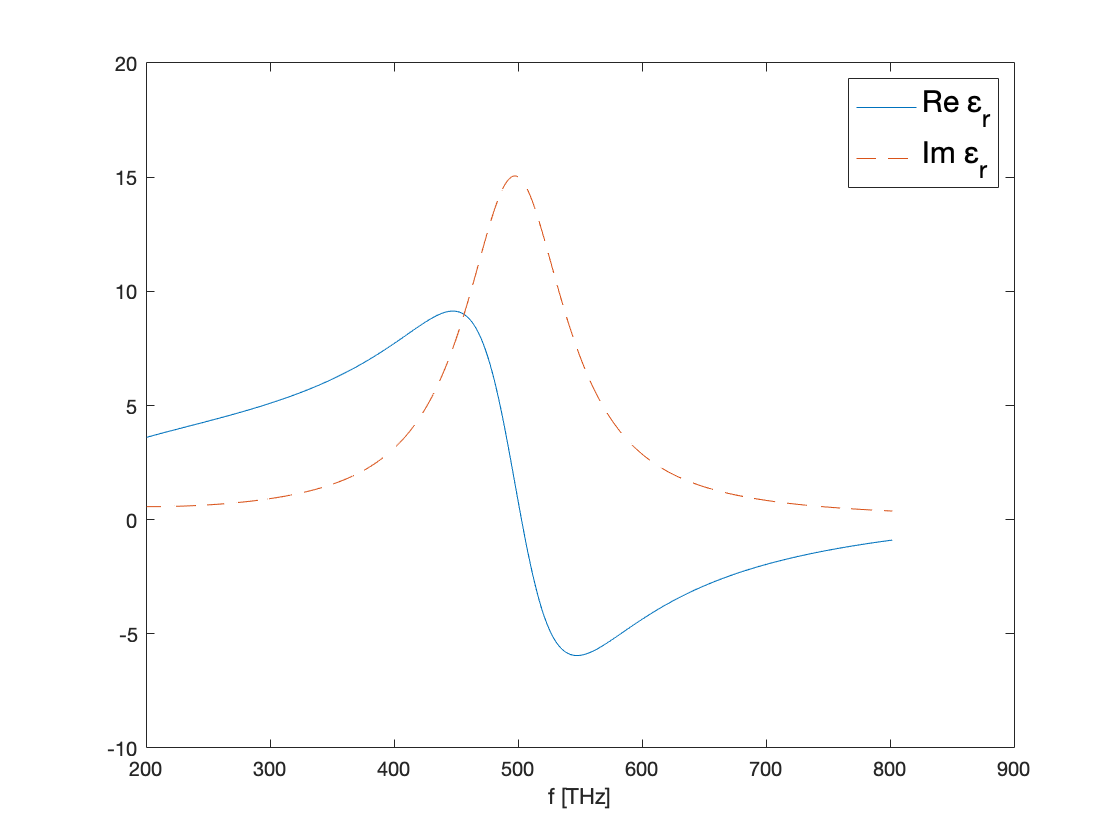

%% theoretical fields
Omega = 2 * pi * Ft;
lorentz = @(w, rel_e, fp, delta) rel_e ./ (1 + 1j * (w / (2 * pi * fp)) * (delta / fp) - (w / (2 * pi * fp)).^2);
drude = @(w, fp, gamma) (2 * pi * fp)^2 ./ (1j * w * (2 * pi * gamma) - w.^2);

% er_func = @(w) (1 + drude(w, 5e14, 2e14));
% er_func = @(w) (1 + lorentz(w, 3, 3e14, 0.5e14) + lorentz(w, 3, 5e14, 1e14));
er_func = @(w) (1 + drude(w, 2e14, 0.5e14) + lorentz(w, 3, 5e14, 1e14));

testf = linspace(0.5 * fp, 2 * fp, 1000);
tester = er_func(2 * pi * testf);

figure(1)
plot(testf / (1e12), real(tester)), hold on
plot(testf / (1e12), -imag(tester), '--'), hold off
legend({['Re ', char(949), '_r'], ['Im ', char(949), '_r']}, 'FontSize', 15)
xlabel('f [THz]')


er =  er_func(Omega);
e = e0 * er;

    
u = u0;
c = 1 ./ sqrt(e * u);
eta = sqrt(u ./ e);
K = Omega ./ c;

Hphi_p = 1 / (4 * pi) * exp(-1j * K .* Rho) .* (1j * K ./ Rho + 1 ./ Rho.^2) .* sin(Th);
Er_p = 1 / (4 * pi) * exp(-1j * K .* Rho) .* (2 * eta ./ Rho.^2 + 2 ./ (1j * Omega .* e .* Rho.^3)) .* cos(Th);
Eth_p = 1 / (4 * pi) * exp(-1j * K .* Rho) .* (1j * Omega .* u ./ Rho + 1 ./ (1j * Omega .* e .* Rho.^3) + eta ./ Rho.^2) .* sin(Th);

Simulated Fields

data = load('data.out');
make_complex = @(x, y) x + 1j * y;
ref = sum(ref_signal .* exp(-1j * 2 * pi * Ft(:) * t), 2);

E = [make_complex(data(:, 1), data(:, 2)), make_complex(data(:, 3), data(:, 4)), make_complex(data(:, 5), data(:, 6))];
H = [make_complex(data(:, 7), data(:, 8)), make_complex(data(:, 9), data(:, 10)), make_complex(data(:, 11), data(:, 12))];

proj_r = [sin(Th(:)) .* cos(Phi(:)), sin(Th(:)) .* sin(Phi(:)), cos(Th(:))];
proj_th = [cos(Th(:)) .* cos(Phi(:)), cos(Th(:)) .* sin(Phi(:)), -sin(Th(:))];
proj_phi = [-sin(Phi(:)), cos(Phi(:)), zeros(size(Phi(:)))];

Er = sum(E .* proj_r, 2) ./ ref;
Eth = sum(E .* proj_th, 2) ./ ref;
Hphi = sum(H .* proj_phi, 2) ./ ref;

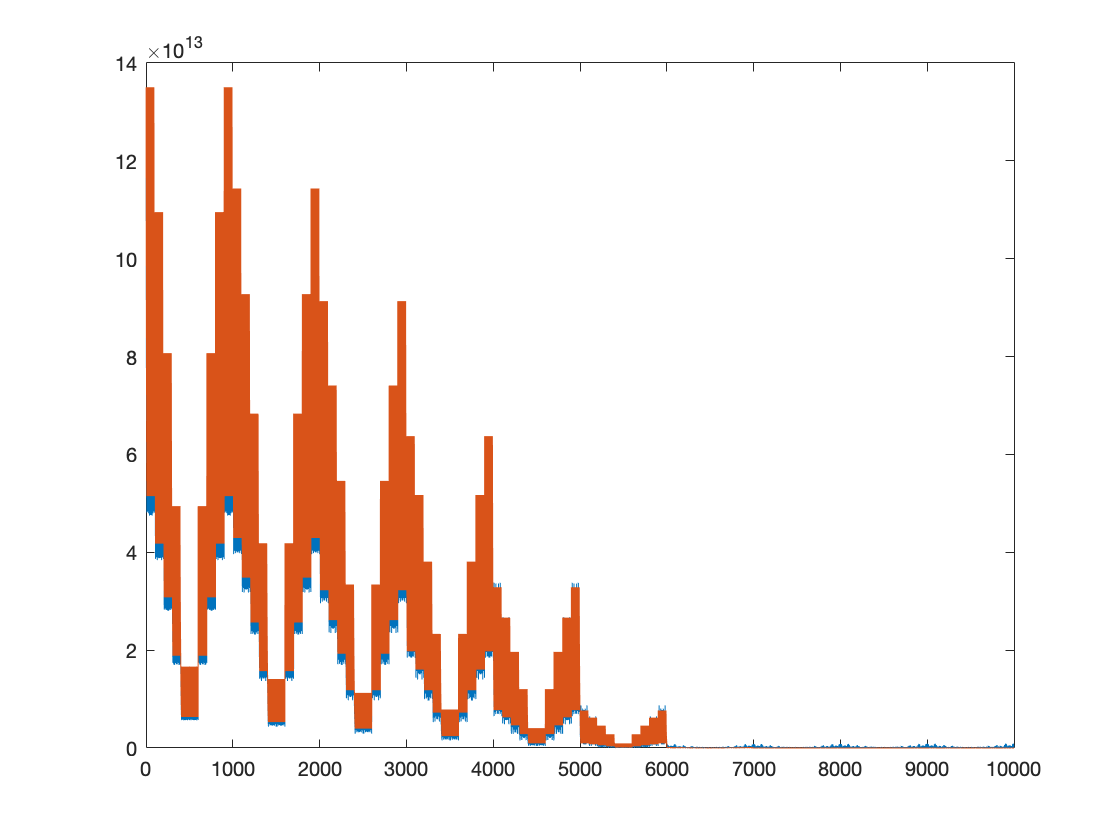

figure(2)
plot(abs(Er(:))), hold on
plot(abs(Er_p(:)))

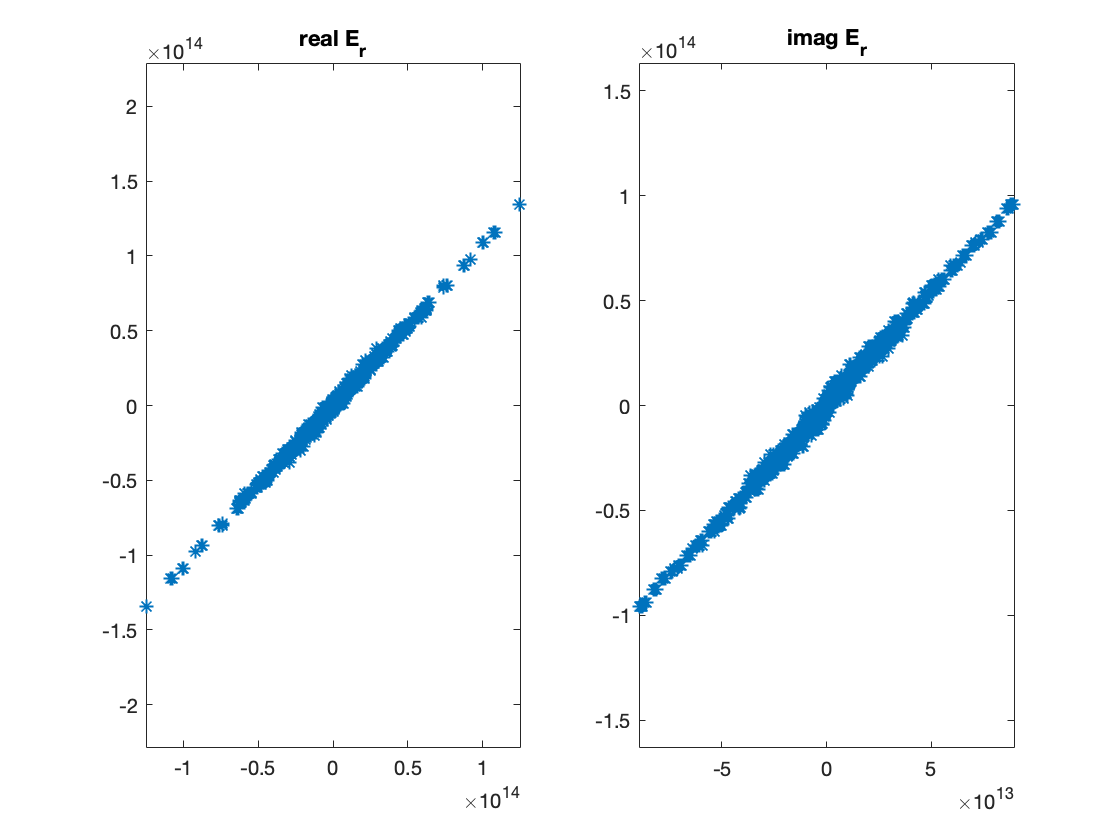

%% correlation comparisons
figure(3)
subplot(1, 2, 1)
plot(real(Er(:)), real(Er_p(:)), '*')
axis equal
title('real E_r')

subplot(1, 2, 2)
plot(imag(Er(:)), imag(Er_p(:)), '*')
axis equal
title('imag E_r')

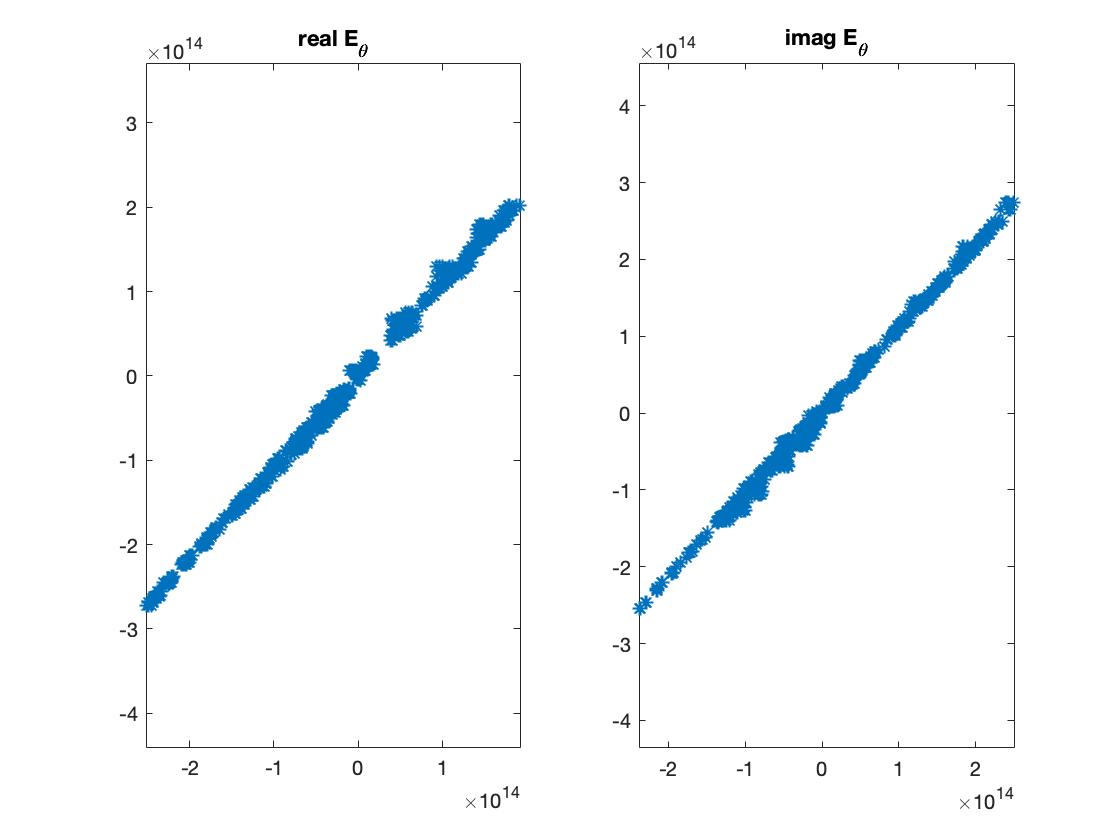


figure(4)
subplot(1, 2, 1)
plot(real(Eth(:)), real(Eth_p(:)), '*')
axis equal
title('real E_\theta')

subplot(1, 2, 2)
plot(imag(Eth(:)), imag(Eth_p(:)), '*')
axis equal
title('imag E_\theta')

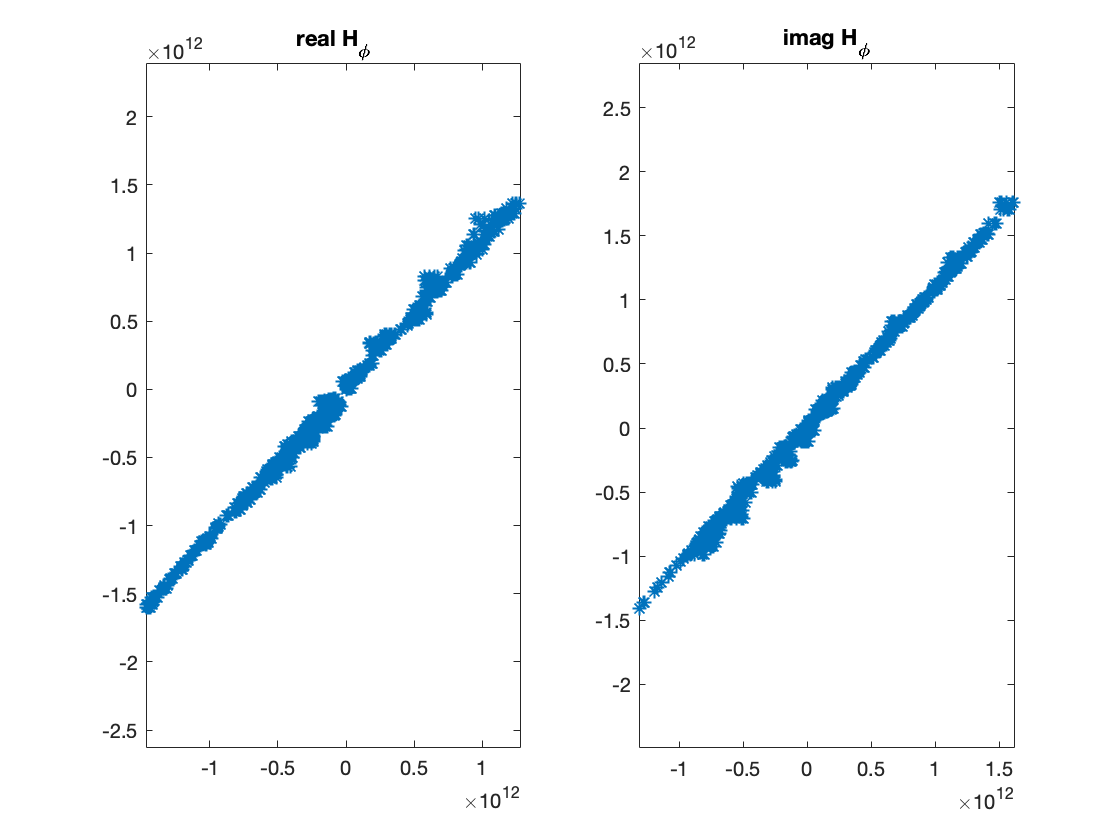


figure(5)
subplot(1, 2, 1)
plot(real(Hphi(:)), real(Hphi_p(:)), '*')
axis equal
title('real H_\phi')

subplot(1, 2, 2)
plot(imag(Hphi(:)), imag(Hphi_p(:)), '*')
axis equal
title('imag H_\phi')